# Noise Analysis

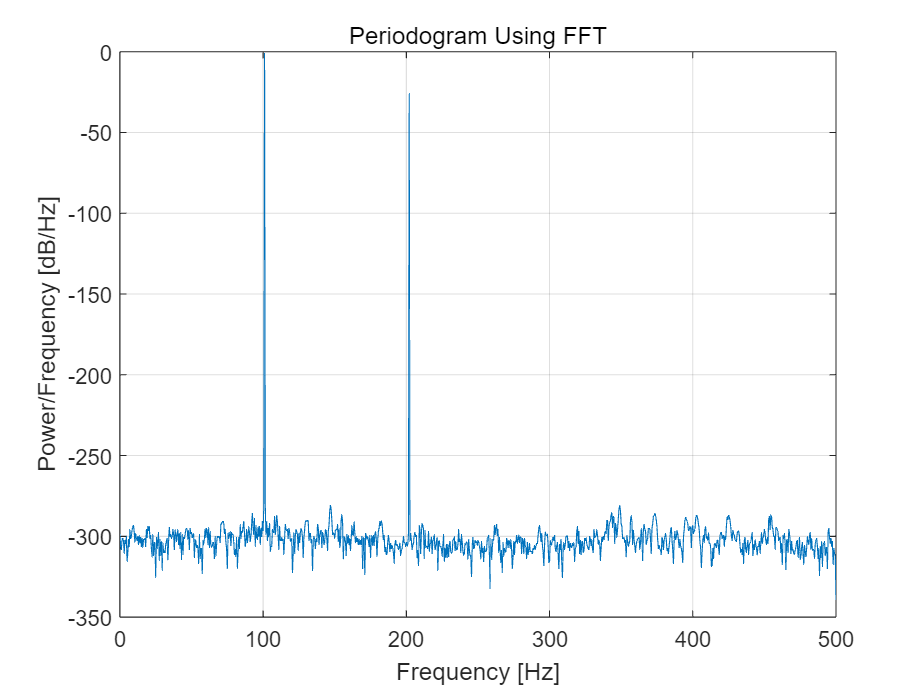

fs = 1000;
t = 0:1/fs:(2-1/fs);
x = 0.85*cos(2*pi*101*t) + 0.05*cos(2*pi*2*101*t);
% x = awgn(x, 90, 'measured');
N = length(x);
xdft = fft(x);
xdft = xdft(1:N/2+1);
psdx = (1/(fs*N)) * abs(xdft).^2;
psdx(2:end-1) = 2*psdx(2:end-1);
freq = 0:fs/N:fs/2;

plot(freq, pow2db(psdx));
grid on
title("Periodogram Using FFT")
xlabel("Frequency [Hz]")
ylabel("Power/Frequency [dB/Hz]")

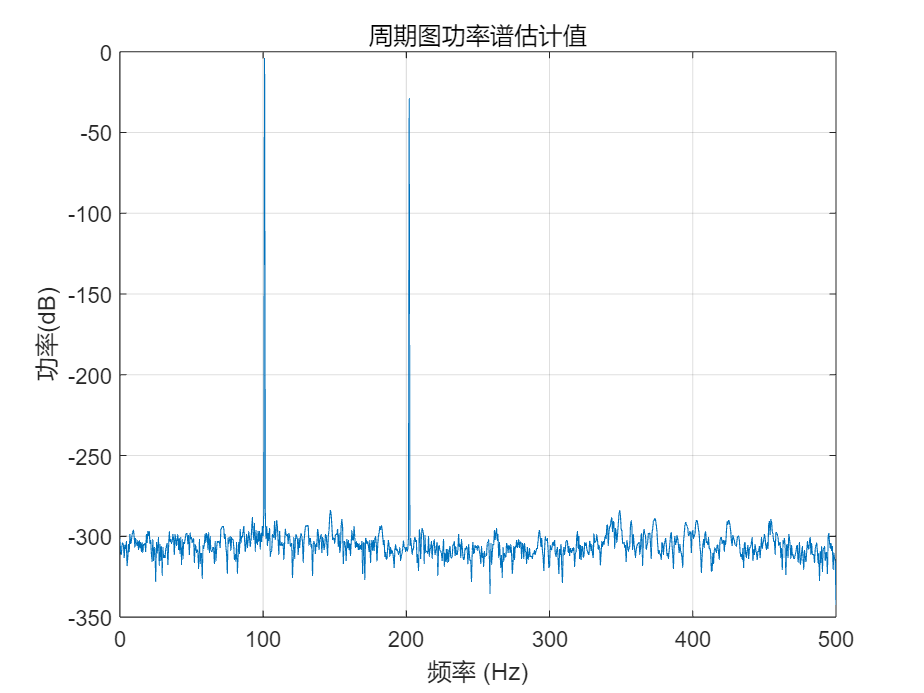

periodogram(x,rectwin(N),N,fs, 'power')

% sinad(repmat(x,[1,32]), fs)
var(x)

ans = 0.3627

std(x)

ans = 0.6022

mean(x.^2)

ans = 0.3625

mean(x)

ans = 8.3156e-16

sum(psdx.* fs/N)

ans = 0.3625

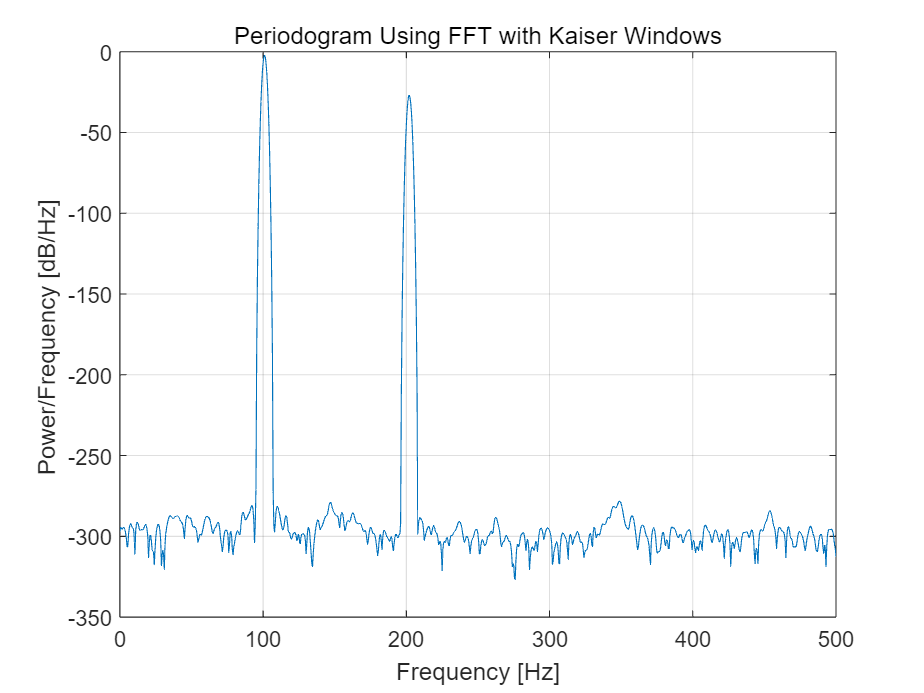


win = kaiser(N,38)';
x_win = x.*win;
xdft = fft(x_win);
xdft = xdft(1:N/2+1);
psdx = (1/(fs*N)) * abs(xdft).^2 * sqrt(sum(win));
psdx(2:end-1) = 2*psdx(2:end-1);
freq = 0:fs/N:fs/2;

plot(freq, pow2db(psdx));
grid on
title("Periodogram Using FFT with Kaiser Windows")
xlabel("Frequency [Hz]")
ylabel("Power/Frequency [dB/Hz] ")

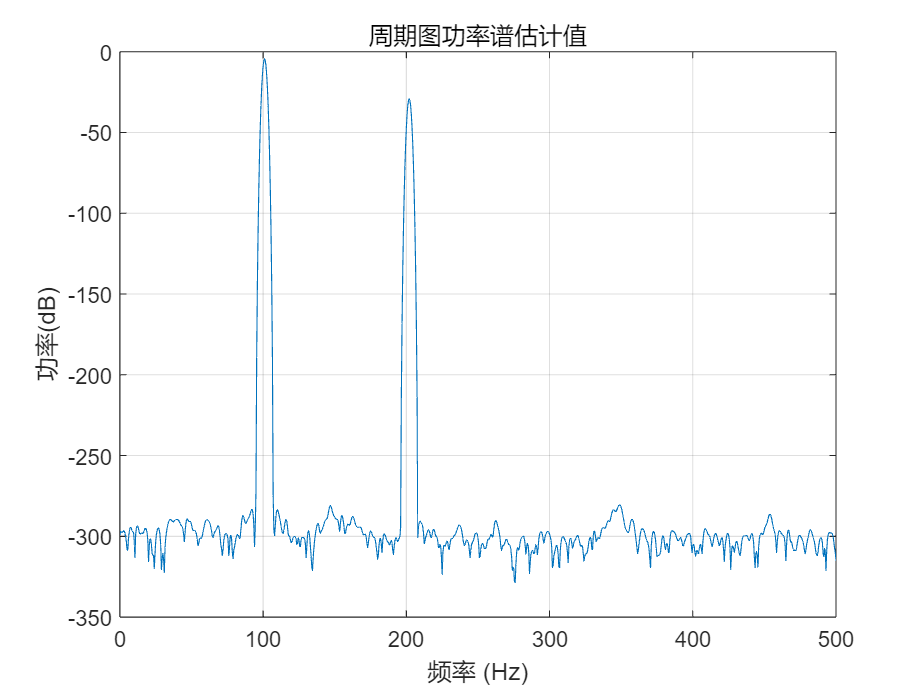

periodogram(x,kaiser(N,38),N,fs, 'power')

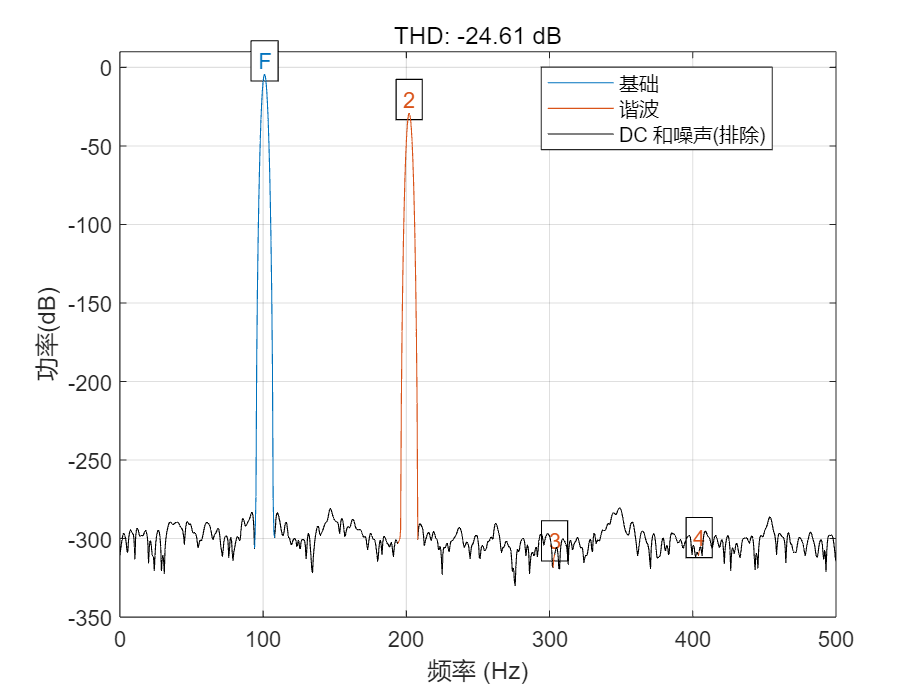

ans = -24.6090

thd(x,fs, 5)

## Calculate THD SNR

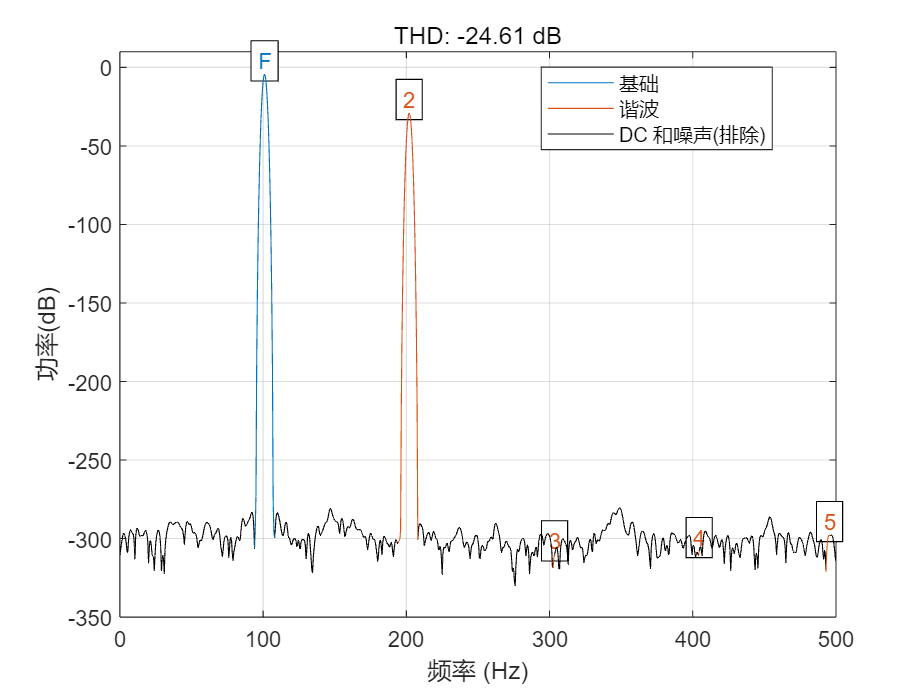

ans = -24.6090

thd(x, fs, 5, "aliased")

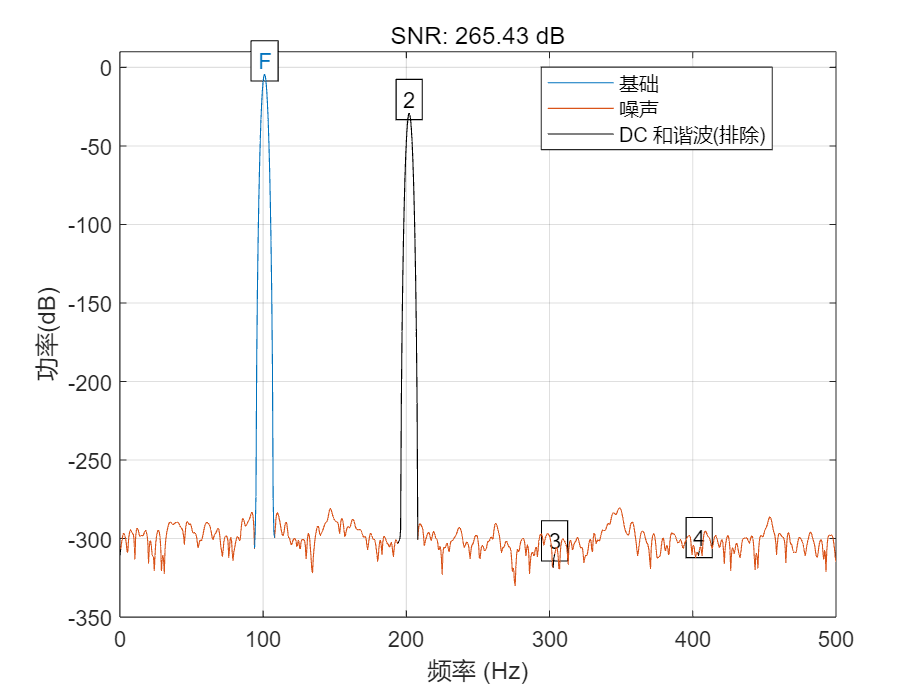

snr(x, fs);

## Mau - THD

xdft_abs = abs(xdft);
fbase_index = find(xdft_abs==max(xdft_abs))

fbase_index = 203

fbase= f(fbase_index)

函数或变量 'f' 无法识别。

harmfre = fbase*(1:4)
harmpow = zeros(1,4)
for i = 1:4
    f_temp = harmfre(i);
    index = find(f==f_temp)
    p_temp = xdft_abs(index)
    harmpow(i) = p_temp;
end
thd = mag2db(sqrt(sum(harmpow(2:end).^2)) / harmpow(1))

## Manually - SNR

psdx_abs = psdx;
for i = 1:4
    f_temp = harmfre(i);
    index = find(f==f_temp);
    psdx_abs(index-10:index+10) = 0;
end

函数或变量 'harmfre' 无法识别。


plot(freq, pow2db(psdx_abs));
grid on
title("Periodogram Using FFT with Kaiser Windows")
xlabel("Frequency [Hz]")
ylabel("Power/Frequency [dB/Hz] ")

% [c,lags] = xcorr(x, 'biased');
% stem(lags,c);
% pow2db(c(lags==0) - mean(x)^2)  

Vnoise = sqrt(sum(abs(psdx_abs)))
% pow2db(harmpow(1))
mag2db(Vnoise/sqrt(harmpow(1)))

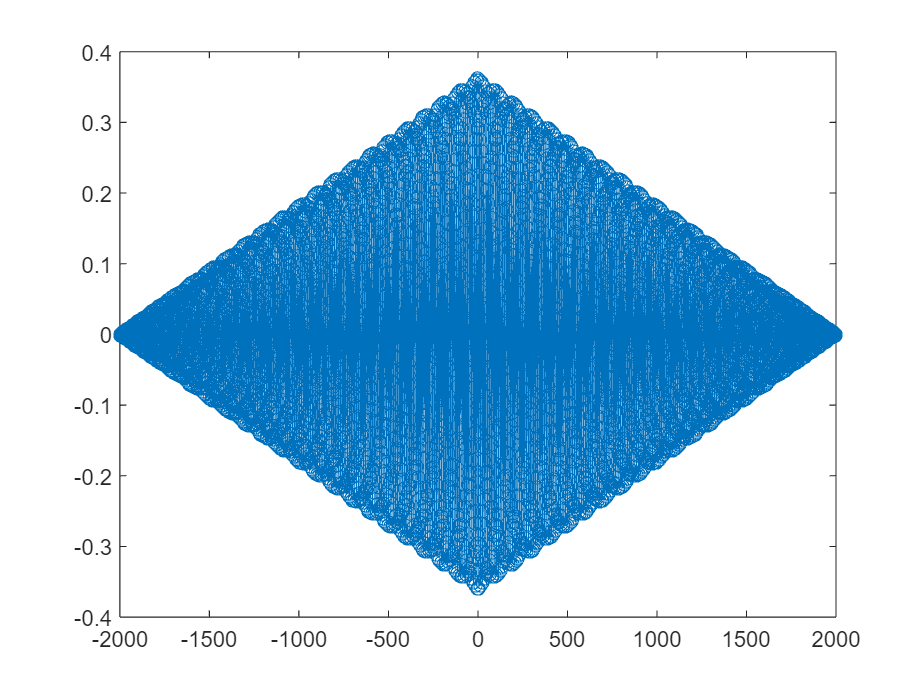

[c,lags] = xcorr(x, 'biased');
stem(lags,c);

c(lags==0) % Power

ans = 0.3625

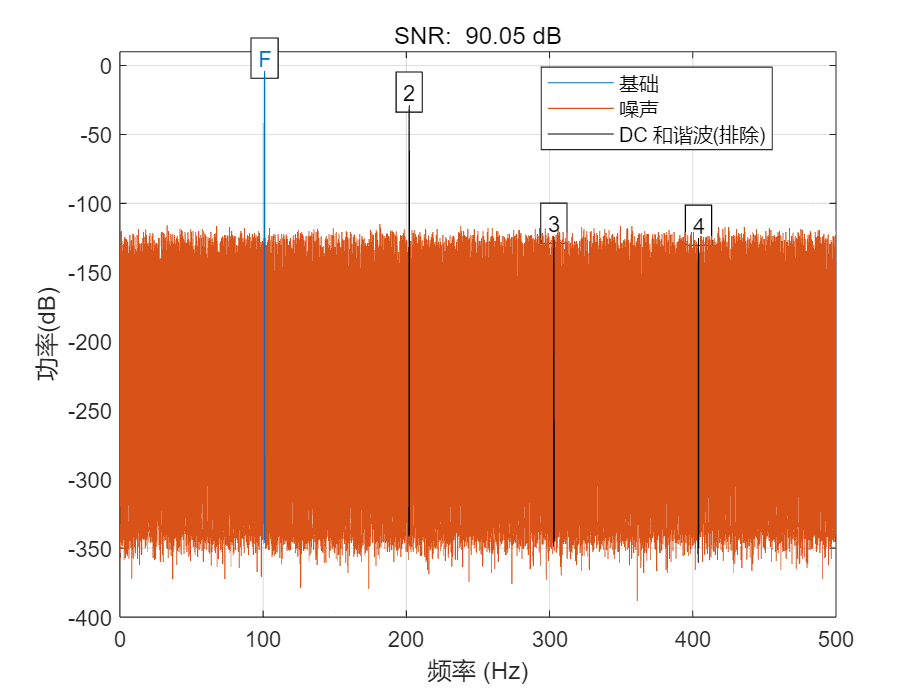

y = awgn(x, 90, 'measured');
snr(repmat(y,[1,32]), fs);

### 当噪声中不含直流分量时，即mx = 0;

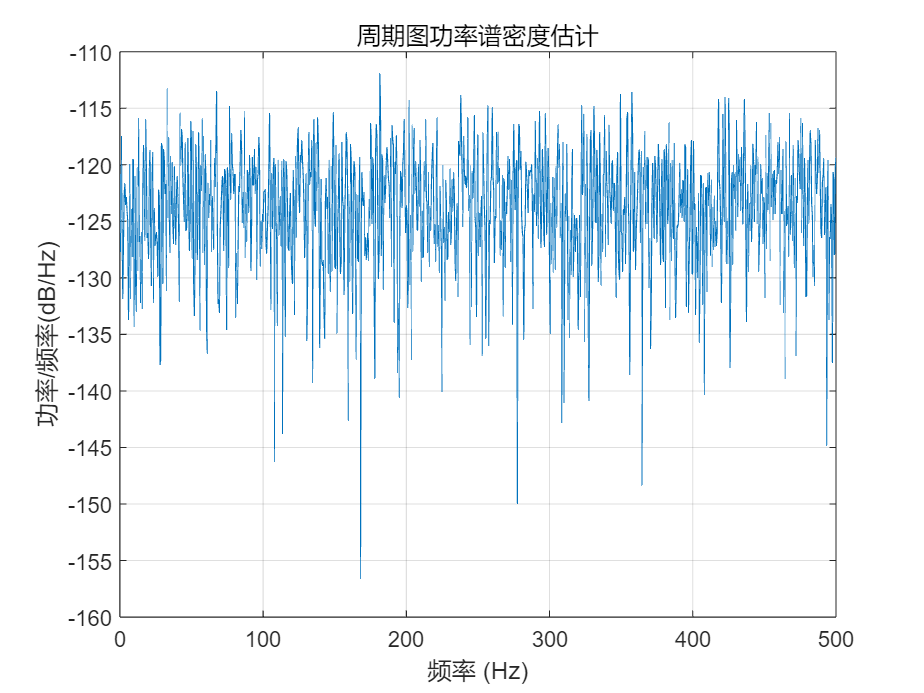

Noise = y - x ;

periodogram(Noise,rectwin(N),N,fs, 'PSD');

法一：噪声（随机信号）的平均功率满足：$R\left(0\right)=E\left\lbrack \zeta^2 \left(t\right)\right\rbrack$

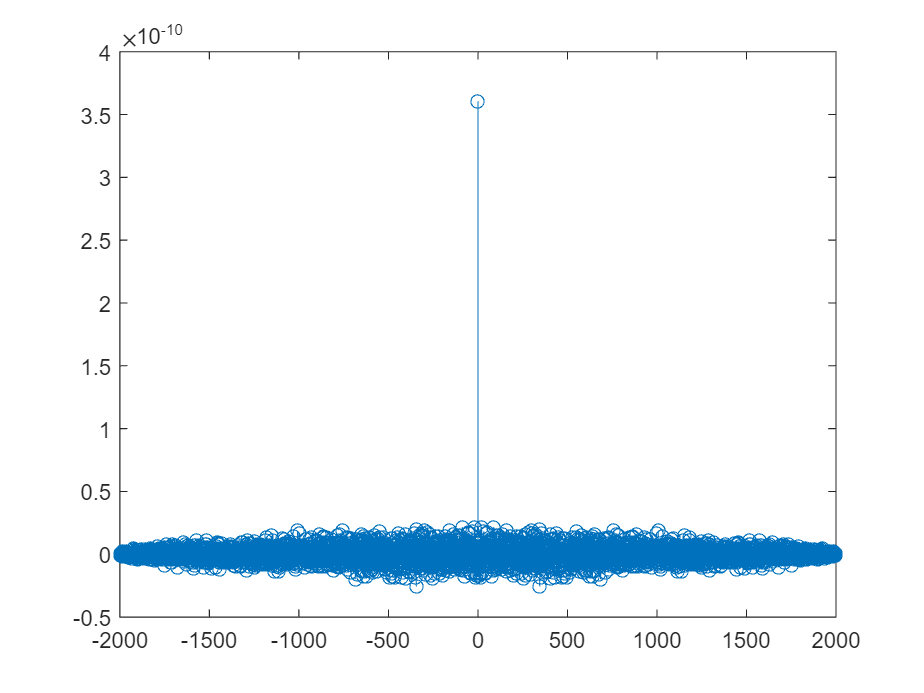

[c,lags] = xcorr(Noise, 'biased');
stem(lags,c);

pow2db(c(lags==0))  % Power

ans = -94.4306

法二：噪声（随机信号）的平均功率满足：$R\left(0\right)=E\left\lbrack \zeta^2 \left(t\right)\right\rbrack =\textrm{Var}\left\lbrack \zeta \left(t\right)\right\rbrack +E^2 \left\lbrack \zeta^2 \left(t\right)\right\rbrack =\textrm{Var}\left\lbrack \zeta \left(t\right)\right\rbrack$

pow2db(var(Noise))

ans = -94.4334

法三：噪声（随机信号）的平均功率可以利用periodogram做PSD分析，求和得到：

[pxx_power, f] = periodogram(Noise,rectwin(N),N,fs, 'power');
pow2db(sum(pxx_power) )

ans = -94.4306

[pxx, ~] = periodogram(Noise,rectwin(N),N,fs, 'psd');
pow2db(sum(pxx *fs/N) )

ans = -94.4306

sum(pxx *fs/N)

ans = 3.6053e-10

sqrt(sum(pxx *fs/N))

ans = 1.8988e-05

### 当噪声中含直流分量时，即mx > 0，此时平均功率不等于噪声功率

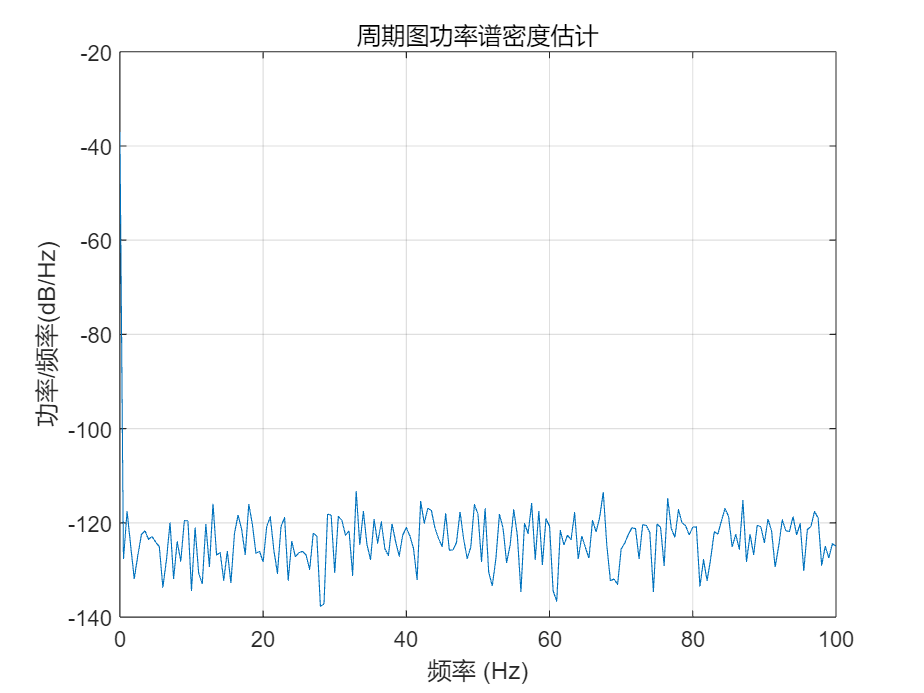

Noise = y - x + 0.01;

periodogram(Noise,rectwin(N),N,fs, 'PSD');

xlim([0 100])

法一：噪声（随机信号）的功率满足：$R\left(0\right)=E\left\lbrack \zeta^2 \left(t\right)\right\rbrack =\textrm{Var}\left\lbrack \zeta \left(t\right)\right\rbrack +E^2 \left\lbrack \zeta \left(t\right)\right\rbrack$

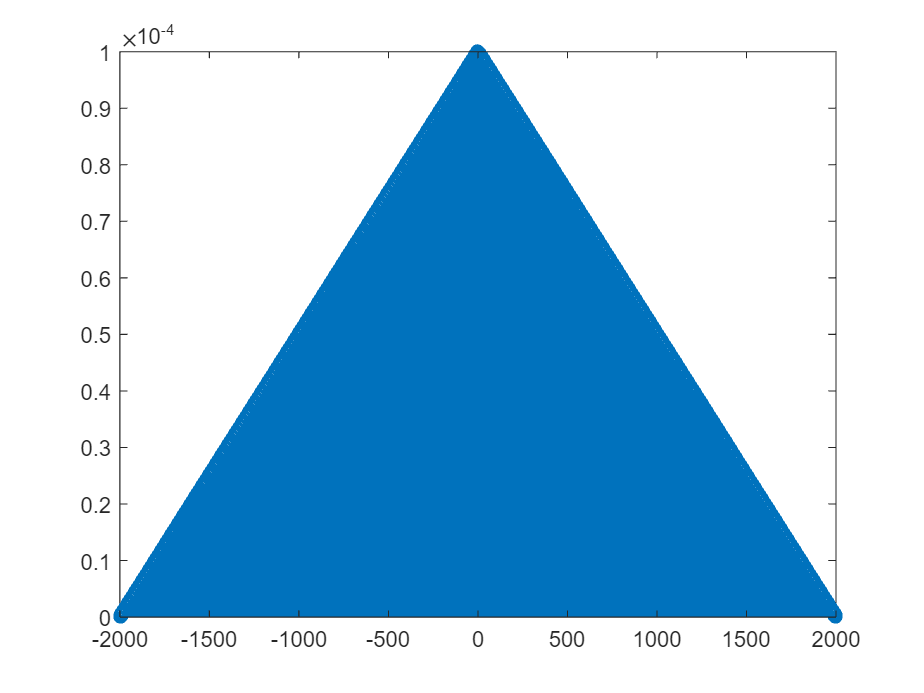

[c,lags] = xcorr(Noise, 'biased');
stem(lags,c);

pow2db(c(lwgs==0) - mean(Noise)^2)  

函数或变量 'lwgs' 无法识别。

法二：噪声（随机信号）的功率等于方差$\textrm{Var}\left\lbrack \zeta \left(t\right)\right\rbrack$

pow2db(var(Noise))

法三：噪声（随机信号）的平均功率可以利用periodogram做PSD分析，求和得到：

[pxx, ~] = periodogram(Noise,rectwin(N),N,fs, 'psd');
pxx(1) = 0;     % 剔除直流分量
pow2db(sum(pxx * (fs/N)) )